First I need to agree what is computed to generate the random numbers.

I will describe a few constants

- timesteps (bit length of output)

- the initial seed needs to be atleast timesteps*2 + 1 length, so needs to be greater than 1

- start state (which will just be one in the middle for now)

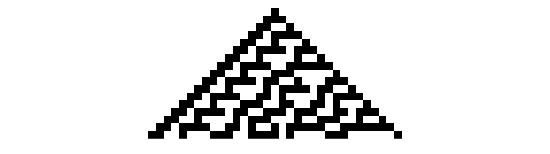

rule30 = [0  0  0  1  1  1  1  0];
seed_radius = 32;
timesteps = 16; % 8 bit fraction from middle row
start_state = [zeros(1, seed_radius) 1 zeros(1, seed_radius)];
eca_visualize(eca_run(start_state, rule30, timesteps), 2000)

asdasd

mean(sample_rule30(start_state, 10000))

ans = 0.4997

asd

[r, new_seed] = sample_rule30(start_state, 10000)

r =     0.8594    0.7695    0.5742    0.6797    0.4570    0.3789    0.5820    0.6680    0.5898    0.7461    0.7695    0.1445    0.9492    0.8008    0.9375    0.0859    0.6719    0.1406    0.1406    0.8555    0.4102    0.4453    0.4336    0.1406    0.6953    0.1445    0.5430    0.7031    0.6562    0.1719    0.7305    0.7109    0.4531    0.2773    0.4414    0.5625    0.0781    0.8438    0.0352    0.6406    0.8633    0.4258    0.0898    0.4375    0.0898    0.8438    0.4180    0.4844    0.7188    0.5234


new_seed =      1     0     0     0     0     0     0     0     0     1     1     1     1     0     0     1     0     0     1     1     0     1     0     0     1     0     1     1     1     1     1     1     0     0     1     0     0     1     0     1     0     1     1     1     1     1     0     1     1     0


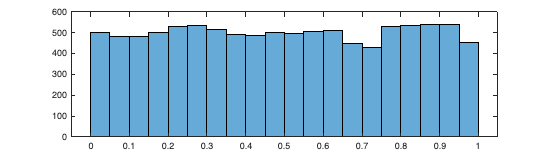

histogram(r)

[r, new_seed] = sample_rule30(new_seed, 10000)

r =     0.3906    0.8633    0.3789    0.4883    0.8828    0.5508    0.0039    0.5000    0.3281    0.7969    0.2773    0.9141    0.6367    0.2812    0.5781    0.3359    0.7109    0.4102    0.6523    0.1562    0.9141    0.7695    0.6484    0.1523    0.8750    0.4922    0.5195    0.3477    0.8633    0.5820    0.1211    0.5664    0.9922    0.8203    0.6211    0.5820    0.6953    0.6992    0.9688    0.8008    0.4766    0.0234    0.0742    0.8438    0.6133    0.5625    0.7461    0.5586    0.5547    0.4453


new_seed =      1     0     0     0     1     1     0     0     0     1     1     0     1     0     0     1     0     1     0     1     0     1     0     1     1     1     1     1     1     1     0     0     1     0     0     0     1     1     1     0     1     0     0     0     1     1     1     0     1     0


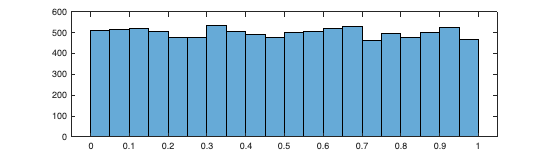

histogram(r)